## [Temperature Control of a Stirred Reactor](https://apmonitor.com/pdc/index.php/Main/StirredReactor)

The objective of this case study is to automatically maintain a temperature in stirred tank reactor with a highly exothermic reaction. This is an example of a highly nonlinear process that is prone to exponential run-away when the temperature rises too quickly.

A reactor is used to convert a hazardous chemical *A* to an acceptable chemical *B* in waste stream before entering a nearby lake. This particular reactor is dynamically modeled as a Continuously Stirred Tank Reactor (CSTR) with a simplified kinetic mechanism that describes the conversion of reactant *A* to product *B* with an irreversible and exothermic reaction. Because the analyzer for product *B* is not fast enough for real-time control, it is desired to maintain the temperature at a constant set point that maximizes the consumption of *A* (highest possible temperature).

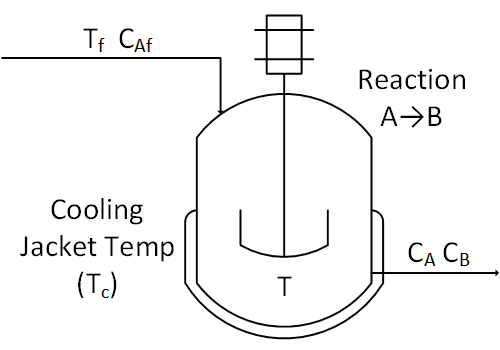

The exercise involves creating a dynamic first-order model, obtaining tuning parameters, and adjusting the PID tuning to achieve acceptable performance.

## Doublet Test for FOPDT Fit

Perform the necessary open loop tests to determine a first order plus dead time (FOPDT) model that describes the relationship between cooling jacket temperature ($MV = T_c
$) and reactor temperature ($CV = T
$). Use the file data.txt to extract the information for the FOPDT model. Obtain an FOPDT model and report the values of the three parameters $K_p, \tau_p, \theta_p$.

Below is a step test example in Python. Modify this to start at 300K for the cooling jacket temperature, step up to 303K, down to 297K, and back to 300K in a doublet test. Fit $K_p, \tau_p, \theta_p$ of an FOPDT model [**using optimization**](https://apmonitor.com/pdc/index.php/Main/FirstOrderOptimization) to achieve the best match to the simulated CSTR data.

Step Test Example

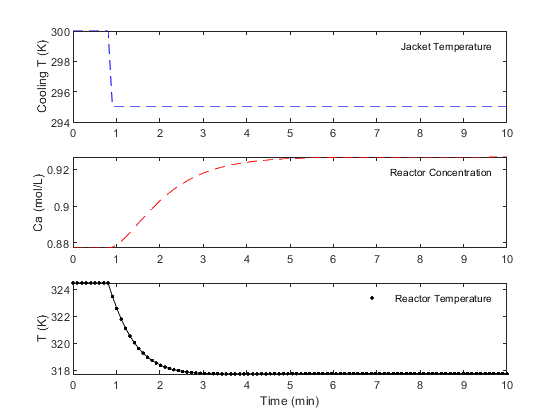



% % animate plots?
% animate=True % True / False

% Steady State Initial Conditions for the States
Ca_ss = 0.87725294608097;
T_ss = 324.475443431599;
x0 = zeros(2,1);
x0(1) = Ca_ss;
x0(2) = T_ss;

% Steady State Initial Condition
u_ss = 300.0;
% Feed Temperature (K)
Tf = 350;
% Feed Concentration (mol/m^3)
Caf = 1;

% Time Interval (min)
t = linspace(0,10,100);
Ts = t(2)-t(1);

% Store results for plotting
Ca = ones(length(t),1) * Ca_ss;
T = ones(length(t),1) * T_ss;
u = ones(length(t),1) * u_ss;

% Step cooling temperature to 295
u(10:end) = 295.0;

% plt.figure(1)

% if animate:
%     plt.ion()
%     plt.show()

% Simulate CSTR
for i = 1:length(t)-1
%     ts = [t(i),t(i+1)]
%     y = odeint(cstr,x0,ts,args=(u(i+1),Tf,Caf))
    [a, h] = ode45(@(a, h) cstr(a, h, u(i+1), Tf, Caf), [0, Ts], x0);

    Ca(i+1) = h(end,1);
    T(i+1) = h(end,2);
    x0(1) = Ca(i+1);
    x0(2) = T(i+1);
end

subplot(3,1,1)
    p1 = plot(t, u, 'b--');
    ylabel('Cooling T (K)')
    legend(p1, {'Jacket Temperature'})
subplot(3,1,2)
    p2 = plot(t, Ca, 'r--');
    ylabel('Ca (mol/L)')
    legend(p2, {'Reactor Concentration'})
subplot(3,1,3)
    p3 = plot(t, T,'k.-');
    ylabel('T (K)')
    xlabel('Time (min)')
    legend(p3, {'Reactor Temperature'})

## Design PI or PID Controller

Use the $K_p, \tau_p, \theta_p$ from the FOPDT model in the [**Internal Model Control (IMC) PI tuning correlation**](https://apmonitor.com/pdc/index.php/Main/ProportionalIntegralControl) or [**PID tuning correlation**](https://apmonitor.com/pdc/index.php/Main/ProportionalIntegralDerivative) to obtain starting values of $K_c
$, $\tau_I$, and $\tau_D$ for a PI or PID controller. Use an aggressive value for the closed loop time constant, $\tau_c$= 0.1$\tau_p$.

## Implement PI or PID Controller

Using $K_c
$, $\tau_I$, and $\tau_D$ from the IMC tuning correlation, implement a PID controller with anti-reset windup. Test the set point tracking capability of this controller by plotting the response of the process to steps in set point of the reactor temperature (not cooling jacket temperature) from 300K up to 320K and then down to 280K. Limit the cooling jacket temperature between 250K and 350K. Comment on how the nonlinear behavior of this process impacts your observed set point response performance.

## Tune PI or PID Controller

Improve the tuning by adjusting $K_c
$, $\tau_I$, and $\tau_D$ by trial and error until the controller displays a 10% to 15% overshoot in response to a reactor temperature set point step from 300K to 320K. Plot this set point step response.

## Challenge: Lowest Concentration

Step up the set point to achieve a maximum temperature in the reactor without exceeding the maximum allowable temperature of 400K (don’t cause a reactor run-away). What is the lowest concentration that can be achieved without exceeding the maximum allowable temperature? This is a very difficult problem due to the potential for reactor temperature run-away. [**Derivative action**](https://apmonitor.com/pdc/index.php/Main/ProportionalIntegralDerivative) may be necessary to achieve the best performance.

The following code is an implementation of a PID controller but is unable to keep the reactor temperature below the upper limit of 400K.

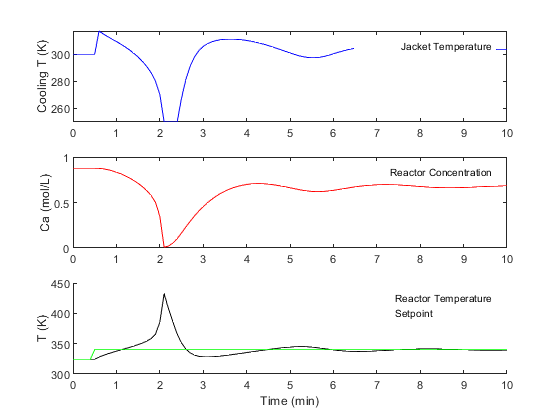

clear
clc
clf 

% Steady State Initial Conditions for the States
Ca_ss = 0.87725294608097;
T_ss = 324.475443431599;
x0 = zeros(2,1);
x0(1) = Ca_ss;
x0(2) = T_ss;

% Steady State Initial Condition
u_ss = 300.0;
% Feed Temperature (K)
Tf = 350;
% Feed Concentration (mol/m^3)
Caf = 1;

% Time Interval (min)
t = linspace(0,10,101);

% Store results for plotting
Ca = ones(length(t),1) * Ca_ss;
T = ones(length(t),1) * T_ss;
u = ones(length(t),1) * u_ss;

% setpoint
sp = ones(101,1) * T_ss;
sp(6:end) = 340.0;
u_bias = u_ss;

% create PID controller
% op = op_bias + Kc * e + Ki * ei + Kd * ed
%      with ei = error integral
%      with ed = error derivative
Kc = 1.0;      % Controller gain
Ki = 1.0;     % Controller integral parameter
Kd = 0.0;      % Controller derivative parameter
% pid = PID(Kc,Ki,Kd)
% lower and upper controller output limits
oplo = 250.0;
ophi = 350.0;
% pid.output_limits = (oplo-u_bias,ophi-u_bias)
% PID sample time
Ts = 0.1;
% pid.sample_time = 0.1

% plt.figure(1)
% plt.ion()
% plt.show()

% timing functions
% tm = np.zeros(101)
% sleep_max = 0.101
% start_time = time.time()
% prev_time = start_time
previousvalue = T(1);
Ierror = 0;
% Simulate CSTR
for i = 1:(length(t)-1)
    % PID control
    T_i = T(i);
    T_sp = sp(i);
    [controlleroutput, Ierror] = pidcontroller(Kc,Ki,Kd, Ts, sp(i), T(i), previousvalue, Ierror, ophi - u_bias, oplo - u_bias, u_bias);
    u(i+1) = controlleroutput + u_bias;
    T_u = u(i+1);

%     ts = [t[i],t(i+1)]
%     y = odeint(cstr,x0,ts,args=(u(i+1),Tf,Caf))
    [a, y] = ode45(@(a, y) cstr(a, y, u(i+1), Tf, Caf), [0, Ts], x0);

    Ca(i+1) = y(end, 1);
    T(i+1) = y(end, 2);
    x0(1) = Ca(i+1);
    x0(2) = T(i+1);
    previousvalue = T(i);

end

subplot(3,1,1)
    p1 = plot(t, u, 'b');
    ylabel('Cooling T (K)')
    legend(p1, {'Jacket Temperature'})
subplot(3,1,2)
    p2 = plot(t, Ca, 'r');
    ylabel('Ca (mol/L)')
    legend(p2, {'Reactor Concentration'})
subplot(3,1,3)
    hold on
    p3 = plot(t, T,'k');
    p4 = plot(t, sp', 'g-');
    ylabel('T (K)')
    xlabel('Time (min)')
    legend([p3 p4],{'Reactor Temperature','Setpoint'})

functions 

function xdot =  cstr(t,x,u,Tf,Caf)
    %define CSTR model
    % Inputs (3):
    % Temperature of cooling jacket (K)
    Tc = u;
    % Tf = Feed Temperature (K)
    % Caf = Feed Concentration (mol/m^3)

    % States (2):
    % Concentration of A in CSTR (mol/m^3)
    Ca = x(1);
    % Temperature in CSTR (K)
    T = x(2);

    % Parameters:
    % Volumetric Flowrate (m^3/sec)
    q = 100;
    % Volume of CSTR (m^3)
    V = 100;
    % Density of A-B Mixture (kg/m^3)
    rho = 1000;
    % Heat capacity of A-B Mixture (J/kg-K)
    Cp = 0.239;
    % Heat of reaction for A->B (J/mol)
    mdelH = 5e4;
    % E - Activation energy in the Arrhenius Equation (J/mol)
    % R - Universal Gas Constant = 8.31451 J/mol-K
    EoverR = 8750;
    % Pre-exponential factor (1/sec)
    k0 = 7.2e10;
    % U - Overall Heat Transfer Coefficient (W/m^2-K)
    % A - Area - this value is specific for the U calculation (m^2)
    UA = 5e4;
    % reaction rate
    rA = k0*exp(-EoverR/T)*Ca;

    % Calculate concentration derivative
    dCadt = q/V*(Caf - Ca) - rA;
    % Calculate temperature derivative
    dTdt = q/V*(Tf - T) + mdelH/(rho*Cp)*rA + UA/V/rho/Cp*(Tc-T);

    % Return xdot:
    xdot = zeros(2,1);
    xdot(1) = dCadt;
    xdot(2) = dTdt;
end
    
function [u, Ierror] = pidcontroller(Kc,Ki,Kd, Ts, setpoint, currentvalue, previousvalue, Ierror, ophi, oplo, u_bias)
    % PID Controller
    %Ierror, the integrator value needs to be passed out and back in
    %If pidcontroller is in a loop, this will be done automatically
    e = setpoint - currentvalue; %calculate error
    Ierror = Ierror + e*Ts; %
    dPVdt = (currentvalue - previousvalue) / (Ts);

    %Adds Gains
    P = Kc * e;
    I = Ki * Ierror;
    D = Kd * dPVdt;
    
    %Calculates controller output
    u = P + I - D;
    %Anti-reset windup, keeps integrator the same if the controller output
    %is maxed out
    if u > ophi
        u = ophi;
        Ierror = Ierror - e * Ts; % anti-reset windup
    elseif u < oplo
        u = oplo;
        Ierror = Ierror - e * Ts; % anti-reset windup
    end
end
    